%----straight line initial condition

%number of points in the trajectory
traj_pt = 2000;

%List of roots
pos_root_arr = double(pos_root_arr)

pos_root_arr =     1.0000    1.0000
    2.0000    2.0000
    2.1654    1.0930
    1.0930    2.1654
    2.8367    1.1633
    1.1633    2.8367
    3.0000    3.0000
    2.9070    1.8346
    1.8346    2.9070



%start & end point
start_idx = 7; end_idx = 8;

%get straight line initial condition joining the end points
q_IC = straight_line_IC(traj_pt,pos_root_arr,start_idx,end_idx);


%For descent 
traj = q_IC;

%lift trajectory
[mom_traj, dt_traj] = lift_traj(traj, eqns_fsolve_fun,Jac_eqns_fsolve_fun,Ham_fun_qp);

%get phase space trajectory and functional gradient 
num_smooth = 10

num_smooth = 10

[PS_traj, delta_x, t_traj] = PS_traj_and_func_grad(traj, mom_traj, ...
    dt_traj, dHamdq_fun,num_smooth);

PS_traj =     3.0000    3.0000         0         0
    3.0000    2.9994   -0.0000   -0.0001
    2.9999    2.9988   -0.0000   -0.0001
    2.9999    2.9983   -0.0000   -0.0001
    2.9998    2.9977   -0.0000   -0.0001
    2.9998    2.9971   -0.0000   -0.0001
    2.9997    2.9965   -0.0000   -0.0001
    2.9997    2.9959   -0.0000   -0.0001
    2.9996    2.9953   -0.0000   -0.0002
    2.9996    2.9948   -0.0000   -0.0002


delta_x =          0         0
   -0.0000    0.0000
   -0.0000    0.0000
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0001
   -0.0000    0.0002
   -0.0000    0.0002
   -0.0000    0.0002


t_traj =          0
    0.0692
    0.1384
    0.2075
    0.2766
    0.3455
    0.4144
    0.4831
    0.5517
    0.6202


plotnam = "Initial condition PS";

model_nam = "2Schlogl"

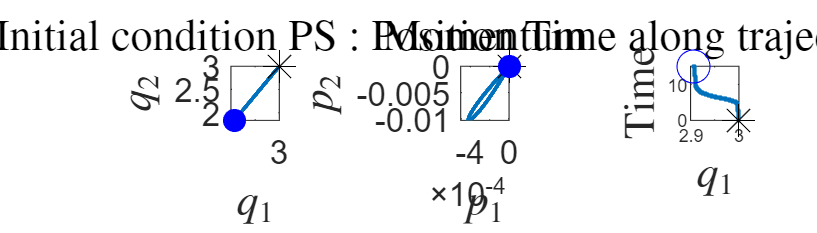

save_plot_name = 'Examples\Plots\'+model_nam+'_IC_PS_traj.png';
save_plot_flag = 0; %change to 1 to save
plot_PS_traj(PS_traj,t_traj,plotnam,save_plot_name,save_plot_flag)